clear

% Read img file
img = imread("../db/DB1/db1_11.jpg")

img = 500×501×3 uint8 array
img(:,:,1) =

   189   183   188   192   196   186   186   189   190   194   186   188   188   182   189   191   194   191   191   188   188   179   187   183   194   189   170   161   194   161   189   191   190   185   185   187   188   191   194   190   189   196   205   206   221   215   218   216   208   198   209   184   217   208   193   195   188   197   195   187   189   191   193   214   199   177    24    32    51    33    60    63    35    60   186   255    76    10    33    26     5    17    27    39    38    52    61    46    13    17    40    20    10    20    16    19    24    26    21    18    32    35    29    24    24    32    13     0    34    41    33    46    43    23    60   190   133   161   174   216   233   230   223   220   203   198   196   200   194   183   170   172   184   186   187   194   201   191   193   210   218   172    99    64    29    29   118   179   139   154   123    67    38    12    16   118   220   230   134    

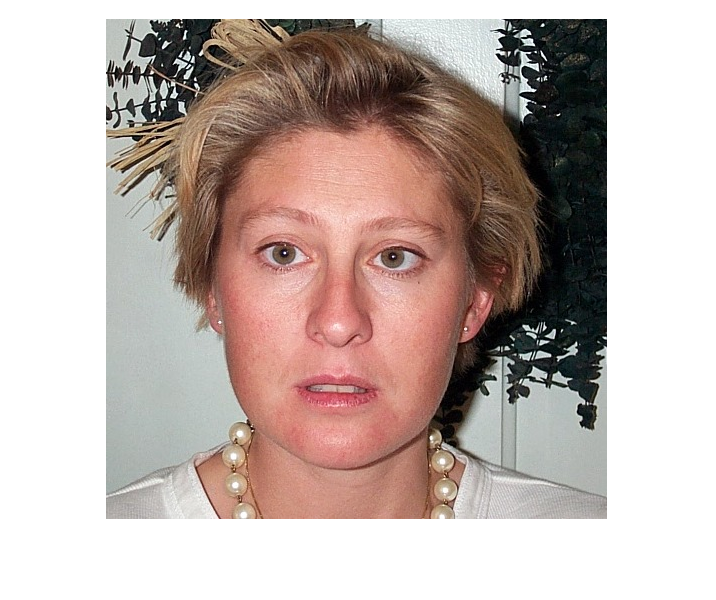

imshow(img)

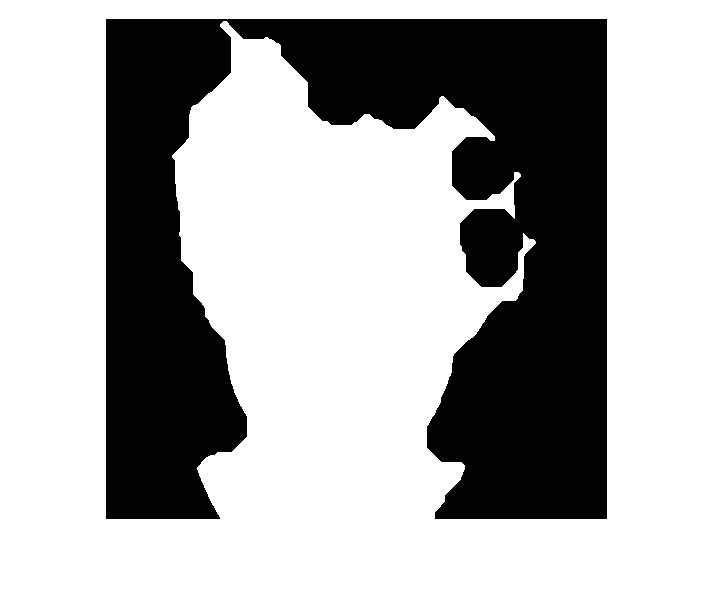

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)


%Find eyes and a mouth
eyes = eyemap(img_gw)

eyes =     0.0710    0.0710    0.0710    0.0710    0.0721    0.0714    0.0714    0.0719    0.0719    0.0739    0.0739    0.0739    0.0739    0.0738    0.0760    0.0789    0.1782    0.1770    0.1770    0.2709    0.2841    0.2816    0.2822    0.2964    0.2985    0.2985    0.3048    0.3021    0.3033    0.3021    0.3033    0.3033    0.3046    0.3039    0.2867    0.6976    0.8011    0.8011    0.7885    0.7885    0.8197    0.8271    0.8271    0.8271    0.8363    0.8289    0.8438    0.8383    0.8233    0.8233
    0.0710    0.0710    0.0710    0.0710    0.0714    0.0714    0.0714    0.0719    0.0727    0.0739    0.0739    0.0739    0.0739    0.0830    0.1436    0.1436    0.1782    0.1820    0.2811    0.2913    0.2913    0.4963    0.5085    0.5085    0.5085    0.5096    0.5175    0.5167    0.5183    0.5183    0.5178    0.5178    0.3018    0.3039    0.3012    0.7537    0.8011    0.8011    0.7885    0.7885    0.8271    0.8197    0.8271    0.8289    0.8389    0.8408    0.8439    0.8402    0.8123  

eye_mask = eyemask((eyes),face_mask)

eye_mask = 500×501 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

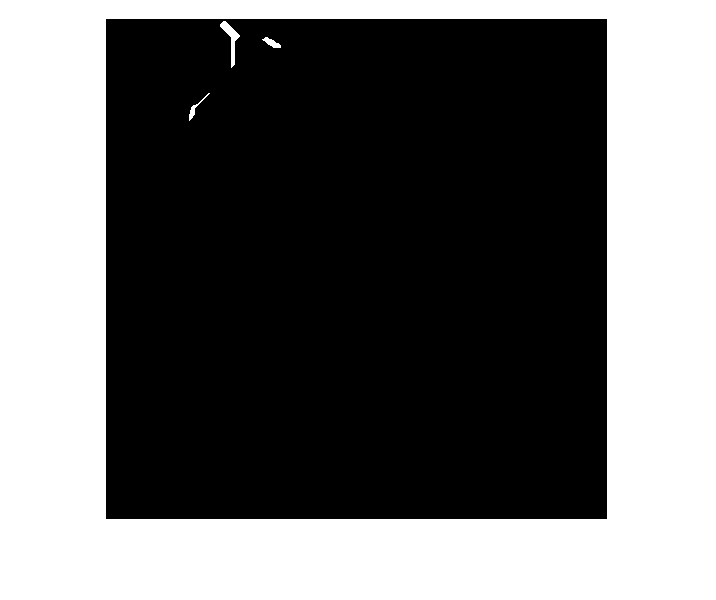



imshow(eye_mask);

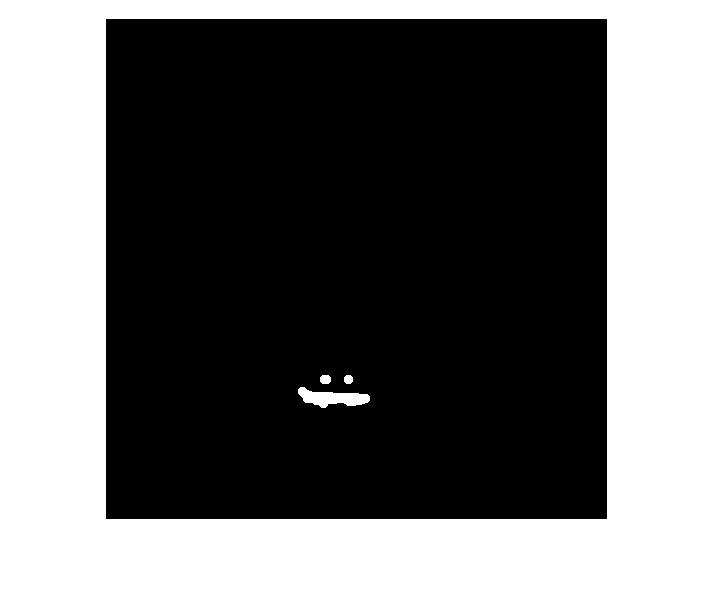


mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask)

x = 361

y = 220

[indexX,indexY] = eye_index(eye_mask)


indexX =

     []


indexY =

     []




% eye_centers = cat(length(indexX),x,y);
%----------------------------------------%
% Calculate the center of the mouth (you might need to adjust this based on your specific case)
mouth_center = [x, y]; % replace with actual coordinates

% Calculate the distance of each eye center from the mouth center
eye_centers = [indexX(:) + indexY(:)/2, indexY(:)];
distances = sqrt(sum((eye_centers - mouth_center).^2, 2));

% Find the indices of the two eyes with the closest distance to the mouth
%[~, sorted_indices] = sort(distances)
%closest_eye_indices = sorted_indices(1:2)
%closest_eyes = [indexX(closest_eye_indices), indexY(closest_eye_indices)]

% Beräkna avståndet mellan varje öga och ansiktets mitt
face_mid = [size(img, 2) / 2, size(img, 1) / 2]; % Mitt av ansiktet
eye_distances_to_mid = sqrt((indexX - face_mid(1)).^2 + (indexY - face_mid(2)).^2);

% Sortera ögonen baserat på avståndet till ansiktets mitt
[sorted_mid_distances, sorted_mid_indices] = sort(eye_distances_to_mid)


sorted_mid_distances =

     []


sorted_mid_indices =

     []




% Välj de två ögonen som är närmast ansiktets mitt
closest_mid_eye_indices = sorted_mid_indices(1:2)

Index exceeds the number of array elements. Index must not exceed 0.

closest_mid_eyes = [indexX(closest_mid_eye_indices), indexY(closest_mid_eye_indices)];

%test

% Visualization
viscircles([closest_mid_eyes(1), closest_mid_eyes(3)], 10);
viscircles([closest_mid_eyes(2), closest_mid_eyes(4)], 10);

eye1 = [closest_mid_eyes(1), closest_mid_eyes(3)];
eye2 = [closest_mid_eyes(2), closest_mid_eyes(4)];


figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')

% Definiera antal pixlar från munnen neråt, ögonen uppåt, samt ögonen utåt
pixels_down_from_eyes = 180; % Antal pixlar från munnen neråt
pixels_up_from_eyes = 50;    % Antal pixlar från ögonen uppåt
pixels_sideways_from_eyes = 40; % Antal pixlar från ögonen utåt

% Beräkna koordinaterna för den nya rektangeln som inkluderar ansiktet
xmin = min([eye1(1), eye2(1)]) - pixels_sideways_from_eyes;
ymin = min([eye1(2), eye2(2)]) - pixels_up_from_eyes;
width = max([eye1(1), eye2(1)]) - xmin + pixels_sideways_from_eyes;
height = max([mouth(2), eye1(2), eye2(2)]) - ymin + pixels_down_from_eyes;

% Säkerställ att det inte går utanför bildens gränser
xmin = max(1, xmin);
ymin = max(1, ymin);
width = min(size(img, 2) - xmin + 1, width);
height = min(size(img, 1) - ymin + 1, height);

% Avrunda koordinaterna för att säkerställa att de är heltal
xmin = round(xmin);
ymin = round(ymin);
width = round(width);
height = round(height);

% Beskär bilden baserat på de beräknade koordinaterna
cropped_img = img(ymin:ymin+height-1, xmin:xmin+width-1, :);

% Visa den beskurna bilden
figure;
imshow(cropped_img)

% Definiera önskad storlek för alla beskurna bilder
desired_height = 400;
desired_width = 300;

% Ändra storleken på den beskurna bilden till önskad storlek
resized_img = imresize(cropped_img, [desired_height, desired_width]);

% Visa den ändrade bilden till önskad storlek
figure;
imshow(resized_img);



